clc
clear, close all
path = 'TrainDatabase';
path=[path '\'];
Filename=dir([path '*.jpg']);
[count,c]=size(Filename);
for i = 1 : count
    f=[path num2str(i) '.jpg'];
    F=imread(f);
    M=rgb2gray(F);
    temp=reshape(M,[200*180 1]);
    K(:,i)=double(temp);%把所有训练图像读到K
end

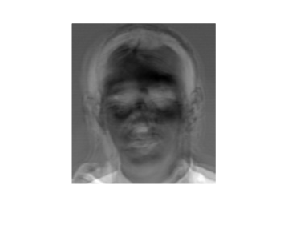

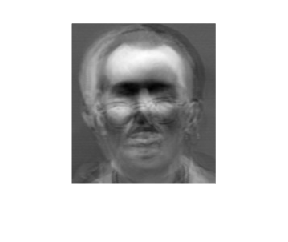

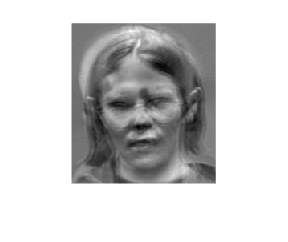

N=3;%滑动指标
[e,m,lambda] = cvpca(K,N);%对K做主成分分析，取N个主成分
for n=1:20
    for i=1:N %利用3个主成分
        p(i,n)=e(:,i)'*K(:,n);%训练图像在特征空间上的投影
    end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%画出特征脸
for i=1:N
   e1=e(:,i);
  tezhenglian=reshape(e1',200,180);
  figure;
   imshow(tezhenglian,[])
end

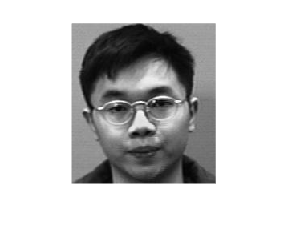

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

im = imread('TestDatabase\4.jpg');%%%%读出测试图像
g=rgb2gray(im);
figure;  imshow(g);    %%%%显示测试图像

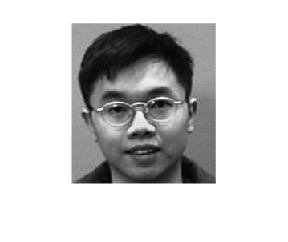

h=reshape(g,[200*180 1]);
L(:,1)=double(h);
pc=e'*L(:,1);%测试图像在特征空间中的投影
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for m=1:20
    d(m)=sum((pc(:,1)-p(:,m)).^2);%测试图像在特征空间中的投影与训练图像在特征空间中投影的距离
end
posi=find(d==min(d));%找距离最小的一个
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%把利用主成份分析在训练样本库中找到的与测试图距离最小的图像显示出来
f=[path num2str(posi) '.jpg'];
f1=imread(f);
result_image=rgb2gray(f1);
figure;
imshow(result_image)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%把输入的测试图也显示出来
path1= 'TestDatabase';
resu=round(posi/2);
path1=[path1 '\'];
f2=[path1 num2str(resu) '.jpg'];
f3=imread(f2);
result_image1=rgb2gray(f3);
figure;
imshow(result_image1);


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%  t
posi

posi = 7

resu

resu = 4